% cleaning
clc
clear

% importing data
df1=readtable("..\data\experimental-data-1.csv")

df1 = 10×4 table
    dimension    value    uncertainty      uom  
    _________    _____    ___________    _______

     {'d1' }      55          0.5        {'CMT'}
     {'d2' }      60          0.5        {'CMT'}
     {'d3' }      65          0.5        {'CMT'}
     {'d4' }      70          0.5        {'CMT'}
     {'d5' }      75          0.5        {'CMT'}
     {'d6' }      80          0.5        {'CMT'}
     {'d7' }      85          0.5        {'CMT'}
     {'d8' }      90          0.5        {'CMT'}
     {'d9' }      95          0.5        {'CMT'}
     {'d10'}      98          0.5        {'CMT'}


df2=readtable("..\data\experimental-data-2.csv")

df2 = 1000×5 table
    event    distance    time    uncertainty      uom  
    _____    ________    ____    ___________    _______

      1      {'d10'}     819          1         {'C26'}
      2      {'d10'}     799          1         {'C26'}
      3      {'d10'}     818          1         {'C26'}
      4      {'d10'}     819          1         {'C26'}
      5      {'d10'}     815          1         {'C26'}
      6      {'d10'}     817          1         {'C26'}
      7      {'d10'}     818          1         {'C26'}
      8      {'d10'}     798          1         {'C26'}
      9      {'d10'}     819          1         {'C26'}
     10      {'d10'}     819          1         {'C26'}
     11      {'d10'}     819          1         {'C26'}
     12      {'d10'}     817          1         {'C26'}
     13      {'d10'}     8

tools=readtable("..\data\tools.csv")

tools = 2×3 table
                tool                uncertainty      uom  
    ____________________________    ___________    _______

    {'proximity sensor tmd4906'}        0.05       {'SEC'}
    {'graduated rod'           }       0.005       {'MTR'}



% unique distance
hd=unique(df2.distance);
ld=length(hd);

% defining variable
l0=1;       % pendulum length
g=9.8;      % gravitational acceleration
dg=0.1;     % error gravitational acceleration
dt=tools.uncertainty(1);    % error t
dr=tools.uncertainty(2);    % errror distance

% creating empty array
tm=zeros(ld,1);     % tempi medi
dtm=zeros(ld,1);    % error t
d=zeros(ld,1);      % distance from CM
dd=zeros(ld,1);     % error distance
r=[0:0.0001:0.5];   % theoretical distance
gc=zeros(ld,1);     % gravitational acceleration calculated
dgc=zeros(ld,1);    % error gc
regc=zeros(ld,1);   % relative error gravitational acceleration

% multiply *2 and converttng ms2s
for i=1:height(df2)
    df2.time(i)=df2.time(i).*2./1000;
    
    % rounding
    df2.time(i)=round(df2.time(i),2);
end


% core
for i=1:ld
    % calculating mean and converting ms2s
    tm(i)=mean(table2array(df2(df2.distance==string(hd(i)),"time")));
    
    % error t
    % dtm(i)=round(std(table2array(df2(df2.distance==string(hd(i)),"time"))),2);
    dtm(i)=dt;

    % distance from CM
    d(i)=table2array(df1(df1.dimension==string(hd(i)),"value"));
    d(i)=d(i)-50;
    d(i)=d(i)/100; %cm2m
    
    % error distance from CM
    dd(i)=dr;

    % gravitational acceleration
    gc(i)=(l0.^2.*pi.^2)./(3.*d(i).*tm(i).^2)+(4.*pi.^2.*d(i))./(tm(i).^2);
    dgc(i)=((pi.^2).*2.*l0.*dd(i))./(3.*d(i).*tm(i).^2)  +  (((((l0.^2).*pi.^2)/(3.*d(i).*tm(i).^4))+(4.*pi^2.*d(i)./tm(i).^4)).*8.*tm(i).*dtm(i))  +  abs(-((l0.^2.*pi.^2)./(3.*d(i).^2.*tm(i).^2)) + (4.*pi.^2)./(tm(i).^2)).*dd(i);
    regc(i)=round(dgc(i)./gc(i)*100,2);
end

% view array2table
output1=array2table(cat(2,string(hd),d,gc,dgc,regc),"VariableNames",{'configuration','distance_CM','gravitational_acceleration','uncertainty','relative_error'});
output1=sortrows(output1,"distance_CM")

output1 = 10×5 table
    configuration    distance_CM    gravitational_acceleration    uncertainty    relative_error
    _____________    ___________    __________________________    ___________    ______________

        "d1"           "0.05"                "6.8702"              "1.5887"         "23.12"    
        "d2"           "0.1"                 "9.0239"              "2.2214"         "24.62"    
        "d3"           "0.15"                "9.0942"              "2.3244"         "25.56"    
        "d4"           "0.2"                 "9.5408"              "2.5373"         "26.59"    
        "d5"           "0.25"                "9.1865"              "2.3996"         "26.12"    
        "d6"           "0.3"                 "9.3596"              "2.4492"         "26.17"    
        "d7"           "0.35"           

round(mean(gc(2:10)),1)

ans = 9.5000

round(mean(dgc(2:10)),0)

ans = 2


% theoretical curve
tt=(2.*pi./sqrt(g)).*sqrt(((l0.^2)./(12.*r))+r);

% visualizing array
output2=sortrows(array2table(cat(2,string(hd),d,dd,tm,dtm),"VariableNames",{'configuration','distance_CM','uncertainty_distance','time','uncertainty_time'}),"distance_CM")

output2 = 10×5 table
    configuration    distance_CM    uncertainty_distance      time      uncertainty_time
    _____________    ___________    ____________________    ________    ________________

        "d1"           "0.05"             "0.005"           "3.1408"         "0.05"     
        "d2"           "0.1"              "0.005"           "2.0207"         "0.05"     
        "d3"           "0.15"             "0.005"           "1.7501"         "0.05"     
        "d4"           "0.2"              "0.005"           "1.5974"         "0.05"     
        "d5"           "0.25"             "0.005"           "1.5833"         "0.05"     
        "d6"           "0.3"              "0.005"           "1.5611"         "0.05"     
        "d7"           "0.35"             "0.005"           "1.5326"         "0.05"     
       

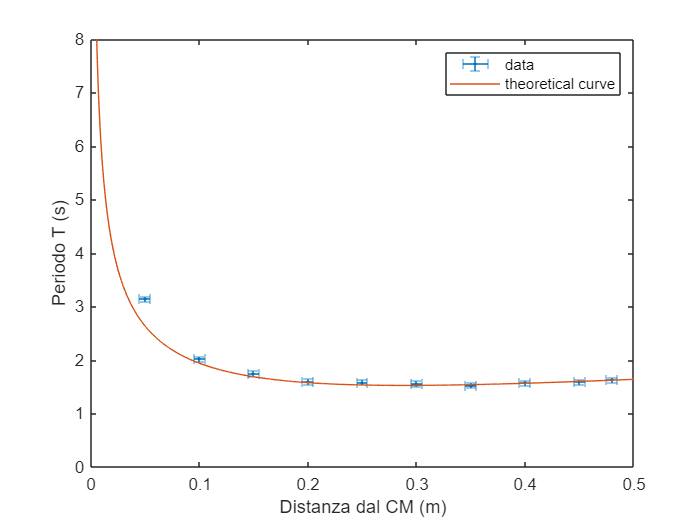


% plotting
plt=figure;
errorbar(d,tm,dtm,dtm,dd,dd,'.')
xlabel('Distanza dal CM (m)')
ylabel('Periodo T (s)')
xlim([0,0.5])
hold on
plot(r,tt)
hold off
ylim([0,8])
legend('data','theoretical curve')

% exporting csv
writetable(output1,'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')
writetable(output2,'..\data\output-data-2.csv','Delimiter',',','Encoding','UTF-8')

% exporting img
saveas(plt,'..\img\plot.png');


% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);